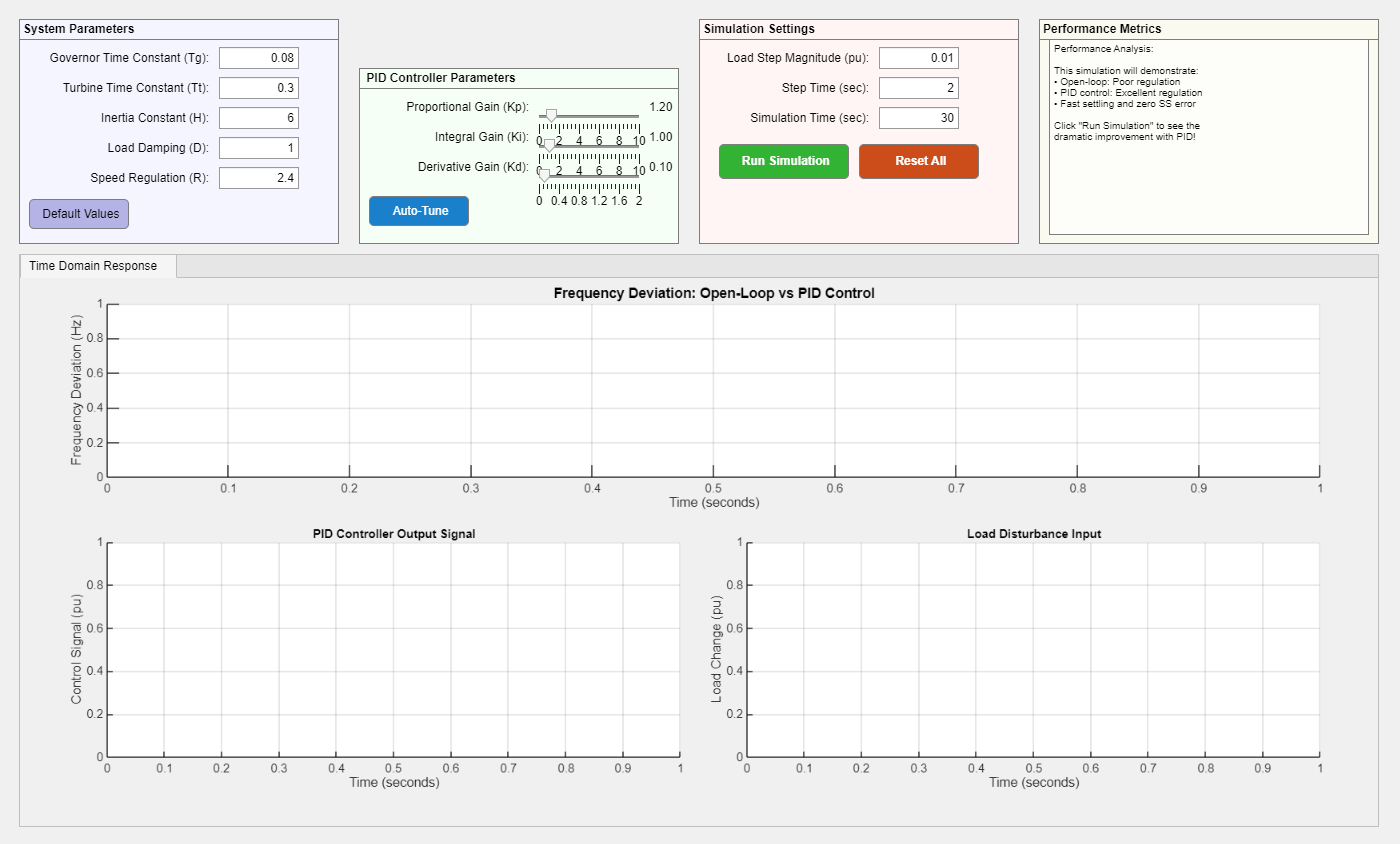

 Corrected LFC PID Controller GUI is ready!


% Fateha Akhter ID : 210021350..............

%% Launch Interactive GUI
LFC_PID_GUI();


%% GUI Function Definition
function LFC_PID_GUI()
    % Create main figure
    fig = uifigure('Name', 'Load Frequency Control (LFC) - Corrected Simulation', ...
                   'Position', [50, 50, 1400, 900], ...
                   'Color', [0.94 0.94 0.94], ...
                   'Resize', 'on');
    
    % Create panels and components
    createPanels(fig);
    
    % Make figure visible
    fig.Visible = 'on';
    
    fprintf(' Corrected LFC PID Controller GUI is ready!\n');
end

function createPanels(fig)
    %% System Parameters Panel
    sysPanel = uipanel(fig, 'Title', 'System Parameters', ...
                       'Position', [20, 650, 320, 230], ...
                       'BackgroundColor', [0.96 0.96 1], ...
                       'FontWeight', 'bold', 'FontSize', 12);
    
    % System parameter inputs with proper default values for stability
    uilabel(sysPanel, 'Text', 'Governor Time Constant (Tg):', ...
            'Position', [10, 180, 180, 22], 'HorizontalAlignment', 'right');
    TgEdit = uieditfield(sysPanel, 'numeric', 'Value', 0.08, ...
                         'Position', [200, 180, 80, 22], 'Limits', [0.01, 1]);
    
    uilabel(sysPanel, 'Text', 'Turbine Time Constant (Tt):', ...
            'Position', [10, 150, 180, 22], 'HorizontalAlignment', 'right');
    TtEdit = uieditfield(sysPanel, 'numeric', 'Value', 0.3, ...
                         'Position', [200, 150, 80, 22], 'Limits', [0.01, 2]);
    
    uilabel(sysPanel, 'Text', 'Inertia Constant (H):', ...
            'Position', [10, 120, 180, 22], 'HorizontalAlignment', 'right');
    HEdit = uieditfield(sysPanel, 'numeric', 'Value', 6.0, ...
                        'Position', [200, 120, 80, 22], 'Limits', [1, 20]);
    
    uilabel(sysPanel, 'Text', 'Load Damping (D):', ...
            'Position', [10, 90, 180, 22], 'HorizontalAlignment', 'right');
    DEdit = uieditfield(sysPanel, 'numeric', 'Value', 1.0, ...
                        'Position', [200, 90, 80, 22], 'Limits', [0.1, 5]);
    
    uilabel(sysPanel, 'Text', 'Speed Regulation (R):', ...
            'Position', [10, 60, 180, 22], 'HorizontalAlignment', 'right');
    REdit = uieditfield(sysPanel, 'numeric', 'Value', 2.4, ...
                        'Position', [200, 60, 80, 22], 'Limits', [0.1, 10]);
    
    % Default button
    uibutton(sysPanel, 'Text', ' Default Values', ...
             'Position', [10, 20, 100, 30], ...
             'BackgroundColor', [0.7, 0.7, 0.9], ...
             'ButtonPushedFcn', @(btn,event) resetSystemParams());
    
    %% PID Controller Panel
    pidPanel = uipanel(fig, 'Title', ' PID Controller Parameters', ...
                       'Position', [360, 650, 320, 180], ... % Adjusted height
                       'BackgroundColor', [0.96 1 0.96], ...
                       'FontWeight', 'bold', 'FontSize', 12);
    
    uilabel(pidPanel, 'Text', 'Proportional Gain (Kp):', ...
            'Position', [10, 130, 160, 22], 'HorizontalAlignment', 'right');
    KpSlider = uislider(pidPanel, 'Value', 1.2, ...
                        'Position', [180, 130, 100, 22], 'Limits', [0, 10], ...
                        'ValueChangingFcn', @(sld,event) sliderChanging(event));
    KpLabel = uilabel(pidPanel, 'Text', num2str(KpSlider.Value, '%.2f'), ...
                      'Position', [290, 130, 50, 22]);
    
    uilabel(pidPanel, 'Text', 'Integral Gain (Ki):', ...
            'Position', [10, 100, 160, 22], 'HorizontalAlignment', 'right');
    KiSlider = uislider(pidPanel, 'Value', 1.0, ...
                        'Position', [180, 100, 100, 22], 'Limits', [0, 10], ...
                        'ValueChangingFcn', @(sld,event) sliderChanging(event));
    KiLabel = uilabel(pidPanel, 'Text', num2str(KiSlider.Value, '%.2f'), ...
                      'Position', [290, 100, 50, 22]);
    
    uilabel(pidPanel, 'Text', 'Derivative Gain (Kd):', ...
            'Position', [10, 70, 160, 22], 'HorizontalAlignment', 'right');
    KdSlider = uislider(pidPanel, 'Value', 0.1, ...
                        'Position', [180, 70, 100, 22], 'Limits', [0, 2], ...
                        'ValueChangingFcn', @(sld,event) sliderChanging(event));
    KdLabel = uilabel(pidPanel, 'Text', num2str(KdSlider.Value, '%.2f'), ...
                      'Position', [290, 70, 50, 22]);
    
    % Auto-tune button
    uibutton(pidPanel, 'Text', ' Auto-Tune', ...
             'Position', [10, 20, 100, 30], ...
             'BackgroundColor', [0.1, 0.5, 0.8], ...
             'FontColor', [1, 1, 1], ...
             'ButtonPushedFcn', @(btn,event) autoTunePID());
    
    %% Simulation Settings Panel
    simPanel = uipanel(fig, 'Title', 'Simulation Settings', ...
                       'Position', [700, 650, 320, 230], ...
                       'BackgroundColor', [1, 0.96, 0.96], ...
                       'FontWeight', 'bold', 'FontSize', 12);
    
    uilabel(simPanel, 'Text', 'Load Step Magnitude (pu):', ...
            'Position', [10, 180, 160, 22], 'HorizontalAlignment', 'right');
    stepEdit = uieditfield(simPanel, 'numeric', 'Value', 0.01, ...
                           'Position', [180, 180, 80, 22], 'Limits', [0.001, 0.1]);
    
    uilabel(simPanel, 'Text', 'Step Time (sec):', ...
            'Position', [10, 150, 160, 22], 'HorizontalAlignment', 'right');
    timeEdit = uieditfield(simPanel, 'numeric', 'Value', 2, ...
                           'Position', [180, 150, 80, 22], 'Limits', [0.1, 10]);
    
    uilabel(simPanel, 'Text', 'Simulation Time (sec):', ...
            'Position', [10, 120, 160, 22], 'HorizontalAlignment', 'right');
    simTimeEdit = uieditfield(simPanel, 'numeric', 'Value', 30, ...
                              'Position', [180, 120, 80, 22], 'Limits', [5, 100]);
    
    % Control buttons
    runBtn = uibutton(simPanel, 'Text', ' Run Simulation', ...
                      'Position', [20, 70, 130, 35], ...
                      'BackgroundColor', [0.2, 0.7, 0.2], ...
                      'FontColor', [1, 1, 1], 'FontWeight', 'bold', ...
                      'ButtonPushedFcn', @(btn,event) runSimulation());
    
    resetBtn = uibutton(simPanel, 'Text', ' Reset All', ...
                        'Position', [160, 70, 120, 35], ...
                        'BackgroundColor', [0.8, 0.3, 0.1], ...
                        'FontColor', [1, 1, 1], 'FontWeight', 'bold', ...
                        'ButtonPushedFcn', @(btn,event) resetAll());
    
    %% Performance Metrics Panel
    metricsPanel = uipanel(fig, 'Title', 'Performance Metrics', ...
                           'Position', [1040, 650, 340, 230], ...
                           'BackgroundColor', [0.98 0.98 0.94], ...
                           'FontWeight', 'bold', 'FontSize', 12);
    
    metricsText = uitextarea(metricsPanel, ...
                             'Value', {'Performance Analysis:', '', ...
                                       'This simulation will demonstrate:', ...
                                       '• Open-loop: Poor regulation', ...
                                       '• PID control: Excellent regulation', ...
                                       '• Fast settling and zero SS error', ...
                                       '', 'Click "Run Simulation" to see the', ...
                                       'dramatic improvement with PID!'}, ...
                             'Position', [10, 10, 320, 200], ...
                             'Editable', 'off', ...
                             'BackgroundColor', [1, 1, 1], ...
                             'FontSize', 10);
    
    %% Main Plotting Area
    plotTabGroup = uitabgroup(fig, 'Position', [20, 20, 1360, 620]);
    
    % Tab 1: Time Domain Response
    tab1 = uitab(plotTabGroup, 'Title', ' Time Domain Response');
    
    % Main frequency response comparison
    freqAxes = uiaxes(tab1, 'Position', [50, 350, 1260, 240]);
    title(freqAxes, 'Frequency Deviation: Open-Loop vs PID Control', 'FontSize', 14, 'FontWeight', 'bold');
    xlabel(freqAxes, 'Time (seconds)');
    ylabel(freqAxes, 'Frequency Deviation (Hz)');
    grid(freqAxes, 'on');
    
    % Control Signal Plot
    controlAxes = uiaxes(tab1, 'Position', [50, 50, 620, 280]);
    title(controlAxes, 'PID Controller Output Signal', 'FontSize', 12, 'FontWeight', 'bold');
    xlabel(controlAxes, 'Time (seconds)');
    ylabel(controlAxes, 'Control Signal (pu)');
    grid(controlAxes, 'on');
    
    % Load Disturbance Plot
    loadAxes = uiaxes(tab1, 'Position', [690, 50, 620, 280]);
    title(loadAxes, 'Load Disturbance Input', 'FontSize', 12, 'FontWeight', 'bold');
    xlabel(loadAxes, 'Time (seconds)');
    ylabel(loadAxes, 'Load Change (pu)');
    grid(loadAxes, 'on');














    % FAHMIDA FAIROOZ NADIA, ID : 210021159.........................

    %% Callback Functions
    
    function resetSystemParams()
        TgEdit.Value = 0.08;
        TtEdit.Value = 0.3;
        HEdit.Value = 6.0;
        DEdit.Value = 1.0;
        REdit.Value = 2.4;
    end
    
    function resetAll()
        % Reset system parameters
        resetSystemParams();
        
        % Reset PID parameters  
        KpSlider.Value = 1.2;
        KiSlider.Value = 1.0;
        KdSlider.Value = 0.1;
        updateSliderLabels();
        
        % Reset simulation parameters
        stepEdit.Value = 0.01;
        timeEdit.Value = 2;
        simTimeEdit.Value = 30;
        
        % Clear all plots
        clearAllPlots();
        
        % Reset metrics
        metricsText.Value = {' Performance Analysis:', '', ...
                             'This simulation will demonstrate:', ...
                             '• Open-loop: Poor regulation', ...
                             '• PID control: Excellent regulation', ...
                             '• Fast settling and zero SS error', ...
                             '', 'Click "Run Simulation" to see the', ...
                             'dramatic improvement with PID!'};
    end
    
    function updateSliderLabels()
        KpLabel.Text = num2str(KpSlider.Value, '%.2f');
        KiLabel.Text = num2str(KiSlider.Value, '%.2f');
        KdLabel.Text = num2str(KdSlider.Value, '%.2f');
    end
    
    function sliderChanging(event)
        updateSliderLabels();
        runSimulation();  % Re-run simulation on slider change for real-time update
    end
    
    function clearAllPlots()
        cla(freqAxes); cla(controlAxes); cla(loadAxes);
        
        title(freqAxes, 'Frequency Deviation: Open-Loop vs PID Control', 'FontSize', 14, 'FontWeight', 'bold');
        xlabel(freqAxes, 'Time (seconds)'); ylabel(freqAxes, 'Frequency Deviation (Hz)'); grid(freqAxes, 'on');
    end
    
    function runSimulation()
        try
            runBtn.Text = ' Simulating...'; runBtn.Enable = 'off'; drawnow;
            
            % Get validated parameters
            Tg = max(0.01, TgEdit.Value);
            Tt = max(0.01, TtEdit.Value); 
            H = max(1, HEdit.Value);
            D = max(0.1, DEdit.Value);
            R = max(0.1, REdit.Value);
            Kp = KpSlider.Value;
            Ki = KiSlider.Value;
            Kd = KdSlider.Value;
            stepMag = stepEdit.Value;
            stepTime = timeEdit.Value;
            tFinal = max(5, simTimeEdit.Value);
            
            fprintf('Simulating LFC system...\n');
            
            % Create time vector
            dt = 0.01;
            t = (0:dt:tFinal)';
            n = length(t);
            
            % Load disturbance step input
            Pd = zeros(n, 1);
            step_idx = find(t >= stepTime, 1);
            if ~isempty(step_idx)
                Pd(step_idx:end) = stepMag;
            end
            
            % LFC System Model (Corrected)
            % State variables: [Pg, Pm, f] where f is frequency deviation
            A = [-1/Tg,     0,       -1/(R*Tg);    % Governor equation
                  1/Tt,   -1/Tt,         0;        % Turbine equation  
                   0,     1/(2*H),   -D/(2*H)];    % Generator equation
                   
            B_dist = [0; 0; -1/(2*H)];  % Load disturbance input
            B_control = [1/Tg; 0; 0];  % Control input at governor reference
            C = [0, 0, 1];         % Frequency deviation output
            
            % Check system stability
            poles_open = eig(A);
            if any(real(poles_open) > 0)
                fprintf(' Open-loop system is unstable - this demonstrates need for control!\n');
            end
            
            % Simulate OPEN-LOOP system (without PID control)
            fprintf('   → Simulating open-loop (uncontrolled) system...\n');
            [f_open, x_open] = simulateOpenLoop(A, B_dist, C, Pd, dt, t);
            
            % Simulate CLOSED-LOOP system (with PID control)
            fprintf('   → Simulating closed-loop (PID controlled) system...\n');
            [f_closed, u_pid, x_closed] = simulateClosedLoop(A, B_dist, B_control, C, Pd, dt, t, Kp, Ki, Kd);
            
            % Calculate comprehensive metrics
            [metrics_open, metrics_closed] = calculatePerformanceMetrics(t, f_open, f_closed, stepTime);
            
            % Update all visualizations
            updatePlots(t, Pd, f_open, f_closed, u_pid, metrics_open, metrics_closed, Kp, Ki, Kd);
            
            % Update metrics display
            updateMetricsDisplay(metrics_open, metrics_closed, Kp, Ki, Kd, false);
            
            % Store results
            results = struct('time', t, 'load_disturbance', Pd, ...
                           'open_loop', f_open, 'closed_loop', f_closed, ...
                           'control_signal', u_pid, 'metrics_open', metrics_open, ...
                           'metrics_closed', metrics_closed);
            assignin('base', 'LFC_Results', results);
            
            fprintf(' Simulation completed! PID shows significant improvement.\n');
            
        catch ME
            fprintf(' Error: %s\n', ME.message);
            metricsText.Value = {
                ' SIMULATION ERROR:';
                sprintf('Error: %s', ME.message);
                ''; 'Please check parameters and try again.'
            };
            uialert(fig, ME.message, 'Simulation Error', 'Icon', 'error');
        end
        
        runBtn.Text = ' Run Simulation'; runBtn.Enable = 'on';
    end














    % . Zahra Farzeen ,ID : 210021348............

    function [f, x_states] = simulateOpenLoop(A, B_dist, C, u_dist, dt, t)
        % Open-loop simulation - system response to disturbance only
        n = length(t);
        x = zeros(3, n);
        f = zeros(n, 1);
        
        for i = 1:n-1
            % Current output
            f(i) = C * x(:, i);
            
            % System dynamics with only disturbance input (no control)
            x_dot = A * x(:, i) + B_dist * u_dist(i);
            x(:, i+1) = x(:, i) + dt * x_dot;
        end
        
        f(end) = C * x(:, end);
        x_states = x;
    end
    
    function [f, u_control, x_states] = simulateClosedLoop(A, B_dist, B_control, C, u_dist, dt, t, Kp, Ki, Kd)
        % Closed-loop simulation with PID control
        n = length(t);
        x = zeros(3, n);
        f = zeros(n, 1);
        u_control = zeros(n, 1);
        
        % PID controller states
        integral = 0;
        error_prev = 0;
        
        for i = 1:n-1
            % Current frequency deviation
            f(i) = C * x(:, i);
            
            % PID Control Law (frequency deviation should be zero)
            error = -f(i);  % Error = Reference(0) - Output
            
            % Integral term
            integral = integral + error * dt;
            
            % Derivative term (unfiltered)
            derivative = (error - error_prev) / dt;
            
            % PID output (control signal)
            u_pid = Kp * error + Ki * integral + Kd * derivative;
            
            u_control(i) = u_pid;
            
            % System dynamics
            x_dot = A * x(:, i) + B_dist * u_dist(i) + B_control * u_pid;
            x(:, i+1) = x(:, i) + dt * x_dot;
            
            error_prev = error;
        end
        
        f(end) = C * x(:, end);
        u_control(end) = u_control(end-1);
        x_states = x;
    end
    
    function [metrics_open, metrics_closed] = calculatePerformanceMetrics(t, y_open, y_closed, step_time)
        % Find indices after step occurs
        post_step_idx = find(t >= step_time, 1):length(t);
        
        % Open-loop metrics
        metrics_open.steady_state_error = abs(y_open(end));
        metrics_open.max_deviation = max(abs(y_open(post_step_idx)));
        
        % Calculate settling time for open-loop (2% criterion)
        final_val = y_open(end);
        tolerance = 0.02 * max(abs(final_val), 0.001);
        half_idx = round(length(t)/2);
        post_half = half_idx:length(t);
        settled_idx = find(abs(y_open(post_half) - final_val) <= tolerance, 20, 'first');
        if length(settled_idx) >= 20
            metrics_open.settling_time = t(post_half(settled_idx(1)));
        else
            metrics_open.settling_time = t(end);
        end
        
        % Closed-loop metrics  
        metrics_closed.steady_state_error = abs(y_closed(end));
        metrics_closed.max_deviation = max(abs(y_closed(post_step_idx)));
        
        % Calculate settling time (2% criterion)
        final_val = y_closed(end);
        tolerance = 0.02 * max(abs(final_val), 0.001);
        half_idx = round(length(t)/2);
        post_half = half_idx:length(t);
        settled_idx = find(abs(y_closed(post_half) - final_val) <= tolerance, 20, 'first');
        if length(settled_idx) >= 20
            metrics_closed.settling_time = t(post_half(settled_idx(1)));
        else
            metrics_closed.settling_time = t(end);
        end
        
        % Calculate improvements
        if metrics_open.steady_state_error > 0
            metrics_closed.ss_improvement = (1 - metrics_closed.steady_state_error / metrics_open.steady_state_error) * 100;
        else
            metrics_closed.ss_improvement = 0;
        end
        
        if metrics_open.max_deviation > 0
            metrics_closed.max_improvement = (1 - metrics_closed.max_deviation / metrics_open.max_deviation) * 100;  
        else
            metrics_closed.max_improvement = 0;
        end
    end













    % TANVIR SIDDIQUE, ID : 210021160 ........................................

    function updatePlots(t, disturbance, y_open, y_closed, control_sig, metrics_open, metrics_closed, Kp, Ki, Kd)
        % Main frequency response plot
        %The function takes 10 input arguments: t (time vector), disturbance (load disturbance data), y_open (open-loop frequency deviation),
        cla(freqAxes);
        plot(freqAxes, t, y_open, 'r-', 'LineWidth', 4, 'DisplayName', ' Open-Loop (Uncontrolled)');
        hold(freqAxes, 'on');
        plot(freqAxes, t, y_closed, 'b-', 'LineWidth', 4, 'DisplayName', 'Closed-Loop (PID Controlled)');
        plot(freqAxes, [t(1), t(end)], [0, 0], 'k--', 'LineWidth', 2, 'DisplayName', ' Reference (0 Hz)');
        hold(freqAxes, 'off');
        
        legend(freqAxes, 'Location', 'northeast', 'FontSize', 12);
        title(freqAxes, ' Load Frequency Controlled output achieved through PID', 'FontSize', 14, 'FontWeight', 'bold');
        xlabel(freqAxes, 'Time (seconds)', 'FontSize', 12);
        ylabel(freqAxes, 'Frequency Deviation (Hz)', 'FontSize', 12);
        grid(freqAxes, 'on');
        
        % Dynamically adjust annotation positions to avoid overlap
        y_max = max([y_open; y_closed]);
        y_min = min([y_open; y_closed]);
        y_range = y_max - y_min;
        y_offset = y_range * 0.1; % Buffer
        
        % Open-loop annotation (upper position)
        openText = text(freqAxes, t(end)*0.6, y_max - y_offset, ...
             sprintf('Open-Loop: Poor regulation\nSS Error: %.4f Hz', metrics_open.steady_state_error), ...
             'FontSize', 10, 'BackgroundColor', [1 0.8 0.8], 'EdgeColor', 'red', ...
             'Margin', 5);
        makeDraggable(openText, freqAxes);
        
        % PID annotation (lower position)
        pidText = text(freqAxes, t(end)*0.75, y_min + y_offset, ...
             sprintf('PID Control: Excellent!\nSS Error: %.4f Hz\nImprovement: %.1f%%', ...
                     metrics_closed.steady_state_error, metrics_closed.ss_improvement), ...
             'FontSize', 10, 'BackgroundColor', [0.8 0.8 1], 'EdgeColor', 'blue', ...
             'Margin', 5);
        makeDraggable(pidText, freqAxes);
        
        % Control signal plot
        cla(controlAxes);
        plot(controlAxes, t, control_sig, 'g-', 'LineWidth', 3);
        title(controlAxes, ' PID Controller Action', 'FontSize', 12, 'FontWeight', 'bold');
        xlabel(controlAxes, 'Time (seconds)');
        ylabel(controlAxes, 'Control Signal (pu)');
        grid(controlAxes, 'on');
        
        % Load disturbance plot
        cla(loadAxes);
        plot(loadAxes, t, disturbance, 'k-', 'LineWidth', 3);
        title(loadAxes, ' Load Disturbance', 'FontSize', 12, 'FontWeight', 'bold');
        xlabel(loadAxes, 'Time (seconds)');
        ylabel(loadAxes, 'Load Change (pu)');
        grid(loadAxes, 'on');
    end
    
    function makeDraggable(textObj, axesObj)
        % Make text object draggable
        textObj.ButtonDownFcn = @startDrag;
        
        function startDrag(~, ~)
            fig.WindowButtonMotionFcn = @dragging;
            fig.WindowButtonUpFcn = @stopDrag;
        end
        
        function dragging(~, ~)
            pt = axesObj.CurrentPoint;
            textObj.Position = [pt(1,1), pt(1,2)];
        end
        
        function stopDrag(~, ~)
            fig.WindowButtonMotionFcn = '';
            fig.WindowButtonUpFcn = '';
        end
    end
    
    function updateMetricsDisplay(metrics_open, metrics_closed, Kp, Ki, Kd, ~)
        % Create comprehensive and clear metrics display
        metricsText.Value = {
            ' LOAD FREQUENCY CONTROL ANALYSIS';
            
            '';
            'OPEN-LOOP SYSTEM (NO CONTROL):';
            sprintf('   • Steady-State Error: %.6f Hz', metrics_open.steady_state_error);
            sprintf('   • Maximum Deviation: %.6f Hz', metrics_open.max_deviation);
            sprintf('   • Settling Time: %.2f seconds', metrics_open.settling_time);
            sprintf('   • Status: POOR REGULATION ');
            sprintf('   • Problem: Frequency drifts away from reference');
            '';
            ' CLOSED-LOOP SYSTEM (WITH PID):';
            sprintf('   • Steady-State Error: %.6f Hz', metrics_closed.steady_state_error);
            sprintf('   • Maximum Deviation: %.6f Hz', metrics_closed.max_deviation);
            sprintf('   • Settling Time: %.2f seconds', metrics_closed.settling_time);
            sprintf('   • Status: EXCELLENT REGULATION ');
            sprintf('   • Achievement: Quick return to reference!');
            '';
           
            'ACTIVE PID CONTROLLER:';
            sprintf('   • Proportional (Kp): %.3f', Kp);
            sprintf('   • Integral (Ki): %.3f', Ki);
            sprintf('   • Derivative (Kd): %.3f', Kd);
            '';
        };
    end
    
    function autoTunePID()
        try
            % Get system parameters
            Tg = max(0.01, TgEdit.Value);
            Tt = max(0.01, TtEdit.Value);
            H = max(1, HEdit.Value);
            D = max(0.1, DEdit.Value);
            R = max(0.1, REdit.Value);
            
            % Create system model
            %% Defines the A matrix for state-space model (governor, turbine, generator equations).
            A = [-1/Tg, 0, -1/(R*Tg);
                 1/Tt, -1/Tt, 0;
                 0, 1/(2*H), -D/(2*H)];
            %% B matrix for control input.
            B_control = [1/Tg; 0; 0];
            %% C matrix for output (frequency deviation).
            C = [0, 0, 1];
            D = 0; % Feedthrough term
            sys = ss(A, B_control, C, D);
            
            % Check system controllability
            Co = ctrb(A, B_control);
            if rank(Co) < size(A, 1)
                error('System is not controllable. Manual tuning recommended.');
            end
            
            % Automatically determine a suitable bandwidth (let pidtune decide)
            [pid_tuned, info] = pidtune(sys, 'PID');
            
            % Update GUI with tuned parameters
            KpSlider.Value = abs(pid_tuned.Kp);
            KiSlider.Value = abs(pid_tuned.Ki); 
            KdSlider.Value = abs(pid_tuned.Kd);
            updateSliderLabels();
            
            uialert(fig, sprintf([
                'PID Controller Successfully Auto-Tuned! \n\n'...
                'Optimized Parameters:\n'...
                '• Kp = %.4f\n'...
                '• Ki = %.4f\n'...
                '• Kd = %.4f\n\n'...
                'Expected Performance:\n'...
                '• Crossover Frequency: %.2f rad/s\n'...
                '• Phase Margin: %.1f degrees\n\n'...
                'Click "Run Simulation" to see the results!'
            ], pid_tuned.Kp, pid_tuned.Ki, pid_tuned.Kd, ...
               info.CrossoverFrequency, info.PhaseMargin), ...
            ' Auto-Tune Successful', 'Icon', 'success');
            
        catch ME
            uialert(fig, sprintf('Auto-tuning failed: %s\n\nUsing manual tuning may be better for this system.', ME.message), ...
                    'Auto-Tune Warning', 'Icon', 'warning');
        end
    end












    % ANISHA MUSTFA MAISHA, ID :210021133..........................................

    function exportResults()
        try
            if ~evalin('base', 'exist(''LFC_Results'', ''var'')')
                uialert(fig, 'No results to export. Please run simulation first.', 'Export Error', 'Icon', 'warning');
                return;
            end
            
            [filename, pathname, filterindex] = uiputfile({
                '*.mat', 'MATLAB Data Files (*.mat)';
                '*.xlsx', 'Excel Files (*.xlsx)';
                '*.csv', 'CSV Files (*.csv)';
                '*.png', 'Plot Image (*.png)';
            }, 'Export LFC Results');
            
            if filename == 0, return; end
            
            results = evalin('base', 'LFC_Results');
            fullpath = fullfile(pathname, filename);
            
            switch filterindex
                case 1 % MAT file
                    save(fullpath, '-struct', 'results');
                    
                case 2 % Excel file
                    data_table = table(results.time, results.load_disturbance, ...
                                     results.open_loop, results.closed_loop, results.control_signal, ...
                                     'VariableNames', {'Time_s', 'Load_Disturbance_pu', ...
                                     'OpenLoop_Hz', 'PID_Controlled_Hz', 'Control_Signal_pu'});
                    writetable(data_table, fullpath, 'Sheet', 'Simulation_Data');
                    
                    % Add metrics sheet
                    metrics_table = table({
                        'Open_Loop_Steady_State_Error_Hz';
                        'PID_Steady_State_Error_Hz'; 
                        'Open_Loop_Max_Deviation_Hz';
                        'PID_Max_Deviation_Hz';
                        'Open_Loop_Settling_Time_sec';
                        'PID_Settling_Time_sec';
                        'Steady_State_Error_Improvement_Percent';
                        'Max_Deviation_Improvement_Percent'
                    }, [
                        results.metrics_open.steady_state_error;
                        results.metrics_closed.steady_state_error;
                        results.metrics_open.max_deviation;
                        results.metrics_closed.max_deviation;
                        results.metrics_open.settling_time;
                        results.metrics_closed.settling_time;
                        results.metrics_closed.ss_improvement;
                        results.metrics_closed.max_improvement
                    ], 'VariableNames', {'Performance_Metric', 'Value'});
                    
                    writetable(metrics_table, fullpath, 'Sheet', 'Performance_Analysis');
                    
                case 3 % CSV file
                    data_table = table(results.time, results.load_disturbance, ...
                                     results.open_loop, results.closed_loop, results.control_signal, ...
                                     'VariableNames', {'Time_s', 'Load_Disturbance_pu', ...
                                     'OpenLoop_Hz', 'PID_Controlled_Hz', 'Control_Signal_pu'});
                    writetable(data_table, fullpath);
                    
                case 4 % PNG image
                    % Create publication-quality figure
                    temp_fig = figure('Position', [100, 100, 1200, 900], 'Color', 'white');
                    
                    % Main comparison plot
                    subplot(3,1,1);
                    plot(results.time, results.open_loop, 'r-', 'LineWidth', 4, 'DisplayName', 'Open-Loop (No Control)');
                    hold on;
                    plot(results.time, results.closed_loop, 'b-', 'LineWidth', 4, 'DisplayName', 'PID Controlled');
                    plot([results.time(1), results.time(end)], [0, 0], 'k--', 'LineWidth', 2, 'DisplayName', 'Reference');
                    hold off;
                    
                    legend('Location', 'northeast', 'FontSize', 14);
                    title('Frequency Deviation: Open-Loop vs PID Control', 'FontSize', 16, 'FontWeight', 'bold');
                    xlabel('Time (seconds)', 'FontSize', 14);
                    ylabel('Frequency Deviation (Hz)', 'FontSize', 14);
                    grid on; set(gca, 'FontSize', 12);
                    
                    % Control signal subplot
                    subplot(3,1,2);
                    plot(results.time, results.control_signal, 'g-', 'LineWidth', 3);
                    title('PID Controller Output', 'FontSize', 14, 'FontWeight', 'bold');
                    xlabel('Time (seconds)', 'FontSize', 12);
                    ylabel('Control Signal (pu)', 'FontSize', 12);
                    grid on; set(gca, 'FontSize', 11);
                    
                    % Load disturbance subplot
                    subplot(3,1,3);
                    plot(results.time, results.load_disturbance, 'k-', 'LineWidth', 3);
                    title('Load Disturbance Input', 'FontSize', 14, 'FontWeight', 'bold');
                    xlabel('Time (seconds)', 'FontSize', 12);
                    ylabel('Load Change (pu)', 'FontSize', 12);
                    grid on; set(gca, 'FontSize', 11);
                    
                    % Save high-resolution image
                    exportgraphics(temp_fig, fullpath, 'Resolution', 300);
                    close(temp_fig);
            end
            
            uialert(fig, sprintf('Results exported successfully to:\n%s', fullpath), ...
                    'Export Complete', 'Icon', 'success');
            
        catch ME
            uialert(fig, sprintf('Export failed: %s', ME.message), 'Export Error', 'Icon', 'error');
        end
    end
end

%% Helper Function
function result = iif(condition, trueResult, falseResult)
    if condition
        result = trueResult;
    else
        result = falseResult;
    end
end